clc;
clear;
close all;
addpath(genpath('./XxUtils'));

SavePath = '../dataset/test/Result'; 
DataGTPath = '../dataset/test/Microtubules_matlab-number7-10db/input_gt_images';
data = '10.31';
name = 'traditionalmodel-Microtubules_matlab-number7-10db';

save_test_path = [SavePath '\' data '\' name];
if exist(save_test_path,'dir'), rmdir(save_test_path,'s'); end
mkdir(save_test_path);

%% paraments setting

lamda = 421;%%nm, emission wavelength
stimulation_lamda = 405;%%nm, excitation wavelength
NA = 1.49;%numerical aperture
N = [2.44 4.34 6.5]/2;  %%SFS magnitude provided by each grating in different cicles
phi = [0 30 60]/180*pi; %starting angles of each cicle
illumSteps =[3 3 3];   %pairs of center-symmetric gratings
phase_num = 3;  %SIM needs three images to recover phase information at a specific SFS magnitude and direction
fmask_radius = [1.5,2.8,4.3];%guessed maskes

scale_factor=1;
spsize = 12; % actual size of single unit in the images caputured by CCD
pixel_size = spsize/scale_factor;

%%paraments of waveguide
width = 20*1000;%%nm, width of waveguide
position = [0,0*1000];%center position of imaging region

files_gt = XxSort(XxDir(DataGTPath, '*'));
test_groups_number = 1:length(files_gt);
msssim= zeros([1 length(test_groups_number)]);
psnrs= zeros([1 length(test_groups_number)]);
time= zeros([1 50]);

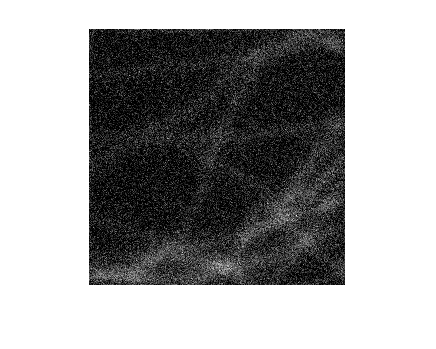

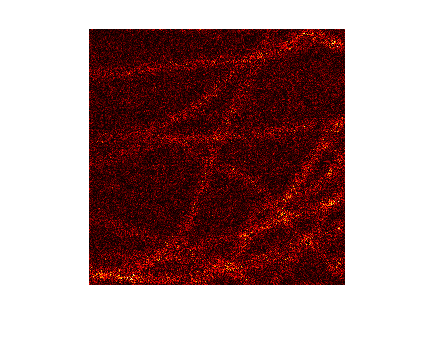

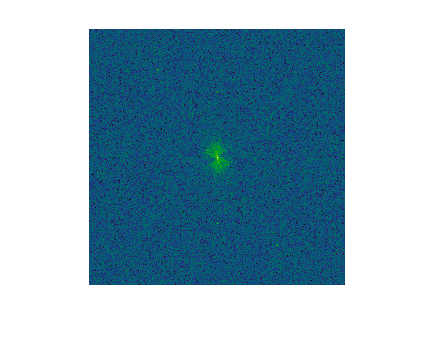

历时 11.509817 秒。


for p = 8
%% read raw images of samples
 Object = double(imread(files_gt{p}));
 Object = XxNorm(Object, 0, 100);
 [n,m]=size(Object);
 max_j = zeros(1); % record the max intensity of wide field

%% OTF calculation
%%To build the coordinate system of Fourier space, where x_size, y_size and pixel_size all refer to GT image
 n1 = n/scale_factor;
 m1 = m/scale_factor;
 fx = -1/spsize/2:1/(spsize*(m1-1)):1/spsize/2;% the coordinates of Fourier space correspond to the coordinates of real space
 fy = -1/spsize/2:1/(spsize*(n1-1)):1/spsize/2;
 [Fx,Fy] = meshgrid(fx,fy);
 CTF = double(sqrt(Fx.^2+Fy.^2)<NA/lamda);%coherent transfer function
 PSF_CTF = ifftshift(ifft2(ifftshift(CTF)));%point spread function in coherent imaging
 factor = numel(CTF)/numel(find(abs(CTF)>0));
%After doing Fourier transform in matlab, the result is multiplied by a parameter compared to the real result. When we do the Fourier inverse transform, we divide this parameter。
%Since the PSF of incoherent imaging is obtained by the square of the PSF of coherent imaging, such a parameter needs to be considered
 PSF_OTF = factor*abs(PSF_CTF).^2;%The point spread function of incoherent imaging
 OTF = fftshift(fft2(fftshift(PSF_OTF)));%Incoherent optical transfer functions

 kyl = 1;
 kxl = 1;
 kyh = n;
 kxh = m;
%% Frequency sprctrum of objects
 object_frequency = fftshift(fft2(fftshift(Object)));
%% Wide-fide
 low_image_1 = abs(ifftshift(ifft2(ifftshift(object_frequency(kyl:kyh,kxl:kxh).*OTF))));
low_image_1= awgn(low_image_1,0,'measured');  %Add Gaussian noise
figure;imshow(low_image_1);
%ide-field image correlation deconvolution
 low_image = deconvlucy(low_image_1,PSF_OTF,5);
 recovered_image = low_image;
 low_image_frequency = fftshift(fft2(fftshift(low_image)));
 OTF_range = double(sqrt(Fx.^2+Fy.^2)<2*NA/lamda);
 recovered_OTF = OTF_range;

 precise_shift_value = zeros(illumSteps(1),2,length(N));%used to store the frequency shift. The first dimension represents the lighting Angle, 2 represents center_x and center_y, and the third dimension represents a certain circle
 tic %Record running time
 for kk = 1:length(N) %Generate evanscent illumination
    theta = phi(kk) : pi/illumSteps(kk) : pi.*(illumSteps(kk)-1)/illumSteps(kk)+phi(kk);%illumination angles of specific circle
    ke = N(kk)*2*pi/stimulation_lamda; %transverse vector of evanscent illmination provided by gratings
    frequency_recovered = fftshift(fft2(fftshift(recovered_image)));
    f_true = zeros(n,m,phase_num,illumSteps(1));%It is used to store the correct reconstructed spectrum with minimum frequency shift. The third dimension represents the number of phases and the fourth dimension represents the number of directions
    shift_phase = zeros(phase_num,illumSteps(1));%It is used to store the three phases calculated when the minimum frequency shift is required. The first dimension represents the number of phases and the second dimension represents the lighting Angle
    
    for tt = 1:illumSteps(kk) %Generates low resolution images of each circle
  
        k1 = ke*cos(theta(tt))+1i*ke*sin(theta(tt));
        k2 = -k1;
        phase = [2*pi/3,4*pi/3,6*pi/3];%The corresponding phase of each grating
        
        x = (-m/2+1:m/2)*pixel_size;
        y = (-n/2+1:n/2)*pixel_size;
        [X,Y]=meshgrid(x,y);
        Y = Y-position(2);
        X = X-position(1);
        r=X+1i*Y;
        k11 = pi/width*1i*conj(k1/abs(k1));
        A1 = cos(real(k11*conj(r)));
        k22 = pi/width*1i*conj(k2/abs(k2));
        A2 = cos(real(k22*conj(r)));
        
        %To store the SFS image with a specific SFS magnitude and direction
        shift_image = zeros(n,m,length(phase));
        shift_image_frequency = zeros(n,m,length(phase));
        
        for jj = 1:length(phase)
            
            E1 = A1.*exp(1i*(real(k1*conj(r))+phase(jj)));
            E2 = A2.*exp(1i*(real(k2*conj(r))));
            E_sum = (E1+E2).*conj(E1+E2)/2;
            object_SIM=E_sum.*Object;   
            object_frequency_SIM=fftshift(fft2(fftshift(object_SIM)));
            image_frequency_SIM=object_frequency_SIM(kyl:kyh,kxl:kxh).*OTF;
            Shiftimage = ifftshift(ifft2(ifftshift(image_frequency_SIM))); 
            Calibration = (A1.^2+A2.^2)/2+0.001;%The average illumination intensity at each position after the two modes interfere
            Shiftimage = abs(Shiftimage./Calibration);%Divide the shot by the lighting intensity distribution
            Shiftimage= awgn(Shiftimage,0,'measured'); 
            
            shift_image(:,:,jj) = deconvlucy(Shiftimage,PSF_OTF,5); %去卷积
            
            shift_image_frequency(:,:,jj)  = fftshift(fft2(fftshift(shift_image(:,:,jj))));
           
        end
       
        if kk >1
           shift_value_lower = precise_shift_value(tt,1,kk-1)+1i*precise_shift_value(tt,2,kk-1);
           shift_value_this = N(kk)/N(kk-1)*abs(shift_value_lower)*exp(1i*(theta(tt)));
        end
        
        if kk==1
           fmask = double(sqrt(Fx.^2+Fy.^2)>fmask_radius(kk)*NA/lamda);
           %figure;imshow(fmask)
        else
           fmask = zeros(n,m);
           fmask = fmask + double(sqrt((Fx+real(shift_value_this)/(pixel_size*(n-1))).^2+(Fy+imag(shift_value_this)/(pixel_size*(n-1))).^2)<0.5*NA/lamda);
           fmask = fmask + double(sqrt((Fx-real(shift_value_this)/(pixel_size*(n-1))).^2+(Fy-imag(shift_value_this)/(pixel_size*(n-1))).^2)<0.5*NA/lamda);
           fmask = fmask .* double(sqrt(Fx.^2+Fy.^2)>fmask_radius(kk)*NA/lamda);%基频与正负频进行相关运算之后，使用fmask将一部分位置的值滤掉，找到的极值则更可靠。
           %figure;imshow(fmask)
        end
        
        %% Fidn the rough shiftvalue of low frequency shift 
        shiftvalue = calculate_shift_value(frequency_recovered,shift_image_frequency,fmask);
        %% Find the fine shiftvalue of the low frequency shift
        precise_shift_value(tt,:,kk) = calculate_precise_shift_value(shiftvalue,frequency_recovered,shift_image_frequency);
        %% The low frequency shift phi1 and the corresponding true phase low_shift_phase of three SIM images were obtained
         
        [phi1,shift_phase(:,tt)] = calculate_phi1(precise_shift_value(tt,:,kk),frequency_recovered,low_image_frequency,shift_image_frequency,fmask);

            %% Figure out the correct low frequency and high frequency according to low_shift_phase f_true_low(:,:,3)
        matrix = [1,0.5*exp(1i*shift_phase(1,tt)),0.5*exp(-1i*shift_phase(1,tt));
                  1,0.5*exp(1i*shift_phase(2,tt)),0.5*exp(-1i*shift_phase(2,tt));
                  1,0.5*exp(1i*shift_phase(3,tt)),0.5*exp(-1i*shift_phase(3,tt))];
        inverse_matrix = inv(matrix);
        re0_temp = zeros(n,m);
        rep_temp = zeros(n,m);
        rem_temp = zeros(n,m);
        
        for ii = 1:length(phase) 
            re0_temp = inverse_matrix(1,ii)*shift_image_frequency(:,:,ii)+re0_temp;
            rep_temp = inverse_matrix(2,ii)*shift_image_frequency(:,:,ii)+rep_temp;
            rem_temp = inverse_matrix(3,ii)*shift_image_frequency(:,:,ii)+rem_temp;
        end
        
         f_true(:,:,1,tt) = re0_temp;
         f_true(:,:,2,tt) = exact_shift(rep_temp,precise_shift_value(tt,:,kk),1);
         f_true(:,:,3,tt) = exact_shift(rem_temp,-precise_shift_value(tt,:,kk),1)   ; 
    end   

factor = 0.001;
x = (-m/2+1:m/2)*pixel_size;
y = (-n/2+1:n/2)*pixel_size;
[X,Y]=meshgrid(x,y);
Y = Y-position(2);
X = X-position(1);
r=X+1i*Y;

%% Reconstruct the high-resolution image according to f true
final_image = zeros(n,m);
theta = phi(kk) : pi/illumSteps(kk) : pi.*(illumSteps(kk)-1)/illumSteps(kk)+phi(kk);
for ttt = 1:illumSteps(kk)
    k1 = ke*cos(theta(ttt))+1i*ke*sin(theta(ttt));
    k2 = -k1;
    k11 = pi/width*1i*conj(k1/abs(k1));
    A1 = cos(real(k11*conj(r)));
    k22 = pi/width*1i*conj(k2/abs(k2));
    A2 = cos(real(k22*conj(r)));
    for iii = 2:3
        raw_image = ifftshift(ifft2(ifftshift(f_true(:,:,iii,ttt))));
        Modu_Cali = 2*A1.*A2./(A1.^2+A2.^2+factor)+factor;
        final_image_sub = raw_image./Modu_Cali;
        final_image = final_image+ final_image_sub;
     end
 end


%equibalent PSF
 OTF_nb = recovered_OTF;
 for tttt = 1:illumSteps(kk)
     OTF_nb = OTF_nb+exact_shift(OTF_range,-precise_shift_value(tttt,:,kk),1)+exact_shift(OTF_range,precise_shift_value(tttt,:,kk),1);
 end
 recovered_OTF = OTF_nb;
 %figure;imshow(abs(OTF_nb))
 
 psf_nb=abs(fftshift(fft2(fftshift(OTF_nb))));
 
 recovered_image = recovered_image + final_image;
 %figure;imshow(recovered_image)
 %figure;imshow(abs(recovered_image)/max(max(abs(recovered_image))));
 
 %figure;imshow(abs(final_image)/max(max(abs(final_image))));
 
 reconstruction_image = deconvlucy(abs(recovered_image),psf_nb,5);
 %reconstruction_image = abs(reconstruction_image)/max(max(abs(reconstruction_image))); 
 end
 
 recovered_image = XxNorm(abs(recovered_image), 0, 100);
 reconstruction_image = XxNorm(abs(reconstruction_image), 0, 100);
 
 color = addcolorplus(302);
 figure(1);imshow(recovered_image)
 colormap('hot')
 print(figure(1), '-dtiff', '-r1000', 'Figure_SIM/Micro_tradition_8.jpg')
 
 ImFF=fftshift(fft2(recovered_image));
 ImFF=log(abs(ImFF));
 ImFF=ImFF/max(max(ImFF));
 
 color = addcolorplus(332);
 figure(2);
 imshow(ImFF);
 colormap(color)
 print(figure(2), '-dtiff', '-r1000', 'Figure_SIM/Micro_tradition_FF8.jpg')

 msssim(p) = multissim(recovered_image,Object);
 psnrs(p) = psnr(recovered_image,Object);
 toc
 time(p)=toc;
 imwrite(recovered_image,[save_test_path '\' num2str(p) '.tif']);
 %imwrite(reconstruction_image,[save_test_path '\' num2str(p) '2.tif']);
end


msssim

msssim =          0         0         0         0         0         0         0    0.5107


psnrs

psnrs =          0         0         0         0         0         0         0   17.5677


mean(msssim)

ans = 0.0638

mean(psnrs)

ans = 2.1960

mean(time)

ans = 0.2302